## Initialization

clc
clear
load("..\DataAndVariables\BaseDefinitions.mat")
load("..\DataAndVariables\AvgValues.mat");
load("Data\ConEst.mat")

measuremedOutputs = [Psch(2:end,:) ; Qsch(2:end,:)];
[Vout, Sout, Sensitivity, J] = NewRapV2(measuremedOutputs(:,1));


noise = 0.0;
PVIndex = [1, 7, 10];%[1,4,7,10,13];%[1, 7, 10]; %[1,2,3,4,5,6,7,8,9,10,11,12,13,14]; % [1, 7, 10, 11, 12]
noPVInv = size(PVIndex,2);
consumptionEstimation = true;
% consumptionEstimationData = measuremedOutputs + (measuremedOutputs .* unifrnd(0,0.10,28,96));
consumptionEstimationData = measuremedOutputs;
Hp = 30;
Hu = 1;
Q = 250*eye(14);
R = eye(noPVInv);
rho = 2500;
uMax = 6;

A = eye(14);
B = Sensitivity(:,PVIndex);

Ts = 1; %How long does a simulation step take [s]
NoSamples = 96; % 96 = all samples
interval = 15; % 15 minutes between data
simTime = NoSamples*((interval * 60) / Ts);
tplot = linspace(0,24,simTime);
T = ((interval * 60) / Ts);
timerDelay = ((5 * 60)/ Ts);
noJump = 0;

U = zeros(noPVInv,simTime);
X = zeros(15+noPVInv,simTime);
S = zeros(28,simTime);
X(:,1) = [Vout(15:end); zeros(noPVInv,1); 1];
S(:,1) = measuremedOutputs(:,1);
j = 1;

%delay stuff
%delay = 302*ones(96,1);
delay = round(lognrnd(5.35,0.4,96,1));

## Without Delay

f = waitbar(0,'1','Name','Simulating',...
    'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');
setappdata(f,'canceling',0);
for t=2:simTime
    % Flow Set Indicator
    if (X(end,t-1) < T)
        [X(:,t), S(:,t)] = FlowMap(X(:,t-1), t, j, S(:,t-1), B, J, noPVInv, measuremedOutputs);
        U(:,t) = U(:,t-1);
    % Jump Set Indicator
    elseif (X(end,t-1) >= T)
        [X(:,t), S(:,t), j, B, J,U(:,t)] = JumpMap(X(:,t-1), S(:,t-1), j, U(:,t-1),Hu, Hp, Q, R, rho, uMax, measuremedOutputs, consumptionEstimation, noPVInv,PVIndex, consumptionEstimationData);
    end

    % Update progress bar and Check for clicked Cancel button
    if getappdata(f,'canceling')
        break
    end
    waitbar(t/simTime,f, sprintf('Simulating step: %i of %i',t, simTime));
end


******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit http://projects.coin-or.org/Ipopt
******************************************************************************



delete(f)

save("Data\SimRes_Hybrid_more_pv_optimal", "t","X","U");

## With Delay

f = waitbar(0,'1','Name','Simulating',...
    'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');
setappdata(f,'canceling',0);
for t=2:simTime
    % Flow Set Indicator
    if (X(end,t-1) < T)
        [X(:,t), S(:,t)] = FlowMap_delay(X(:,t-1), t, j, S(:,t-1), B, J, noPVInv, measuremedOutputs, delay(j));
        U(:,t) = U(:,t-1);
    % Jump Set Indicator
    elseif (X(end,t-1) >= T)
        [X(:,t), S(:,t), j, B, J,U(:,t)] = JumpMap(X(:,t-1), S(:,t-1), j, U(:,t-1),Hu, Hp, Q, R, rho, uMax, measuremedOutputs, consumptionEstimation, noPVInv,PVIndex, consumptionEstimationData);
    end
    % Update progress bar and Check for clicked Cancel button
    if getappdata(f,'canceling')
        break
    end
    waitbar(t/simTime,f, sprintf('Simulating step: %i of %i',t, simTime));
end


******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit http://projects.coin-or.org/Ipopt
******************************************************************************



delete(f)

%save("Data\SimRes_Hybrid_Delay", "t","X","U");
save("Data\SimRes_Hybrid_Delay_Variable", "t","X","U","delay");

## Placement

f = waitbar(0,'1','Name','Simulating',...
    'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');
setappdata(f,'canceling',0);
% [1, 7, 10]
possibleLocations = [2,3,4,5,6,8,9,11,12,13,14];
noPVInv = 4;
R = eye(noPVInv);

for e = 1:length(possibleLocations)
    PVIndex = [1, 7, 10, possibleLocations(e)]
    [Vout, Sout, Sensitivity, J] = NewRapV2(measuremedOutputs(:,1));
    B = Sensitivity(:,PVIndex);
    noJump = 0;
    U = zeros(noPVInv,simTime);
    X = zeros(15+noPVInv,simTime);
    S = zeros(28,simTime);
    X(:,1) = [Vout(15:end); zeros(noPVInv,1); 1];
    S(:,1) = measuremedOutputs(:,1);
    j = 1;

    for t=2:simTime
        % Flow Set Indicator
        if (X(end,t-1) < T)
            [X(:,t), S(:,t)] = FlowMap(X(:,t-1), t, j, S(:,t-1), B, J, noPVInv, measuremedOutputs);
            U(:,t) = U(:,t-1);
        % Jump Set Indicator
        elseif (X(end,t-1) >= T)
            [X(:,t), S(:,t), j, B, J,U(:,t)] = JumpMap(X(:,t-1), S(:,t-1), j, U(:,t-1),Hu, Hp, Q, R, rho, uMax, measuremedOutputs, consumptionEstimation, noPVInv,PVIndex, consumptionEstimationData);
        end
    
        % Update progress bar and Check for clicked Cancel button
        if getappdata(f,'canceling')
            break
        end
        
    end
    waitbar(e/length(possibleLocations),f, sprintf('Simulating step: %i of %i',e, length(possibleLocations)));
    
    save(strcat("Data\SimRes_Hybrid_grid_",num2str(possibleLocations(e))), "t","X","U");
end

PVIndex =      1     7    10     2


PVIndex =      1     7    10     3


PVIndex =      1     7    10     4


PVIndex =      1     7    10     5


PVIndex =      1     7    10     6


PVIndex =      1     7    10     8


PVIndex =      1     7    10     9


PVIndex =      1     7    10    11


PVIndex =      1     7    10    12


PVIndex =      1     7    10    13


PVIndex =      1     7    10    14


delete(f)

## Plotting

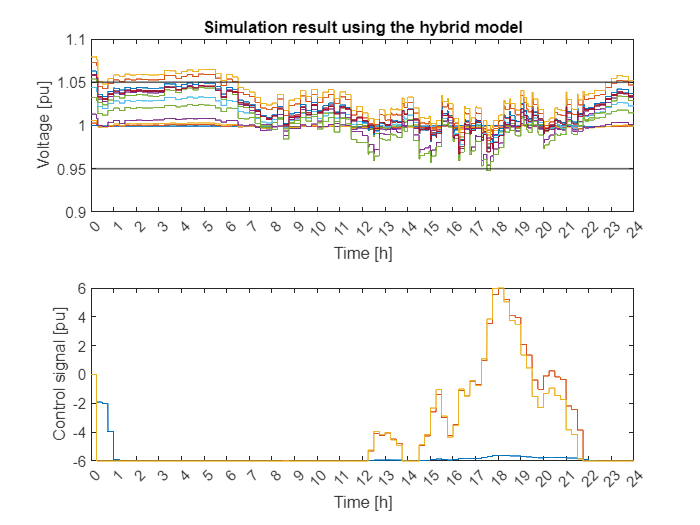

figure()
subplot(2,1,1)
plot(tplot,X(1:14,:)')
yline(0.95, LineWidth=1)
yline(1.05, LineWidth=1)
title("Simulation result using the hybrid model") % using linearisation at each step
ylabel("Voltage [pu]")
xlabel("Time [h]")
ylim([0.9,1.1])
xlim([0,24])
xticks(0:1:24)
subplot(2,1,2)
plot(tplot,U)
ylabel("Control signal [pu]")
xlabel("Time [h]")
ylim([-uMax,uMax])
yticks(-uMax:2:uMax)
xlim([0,24])
xticks(0:1:24)

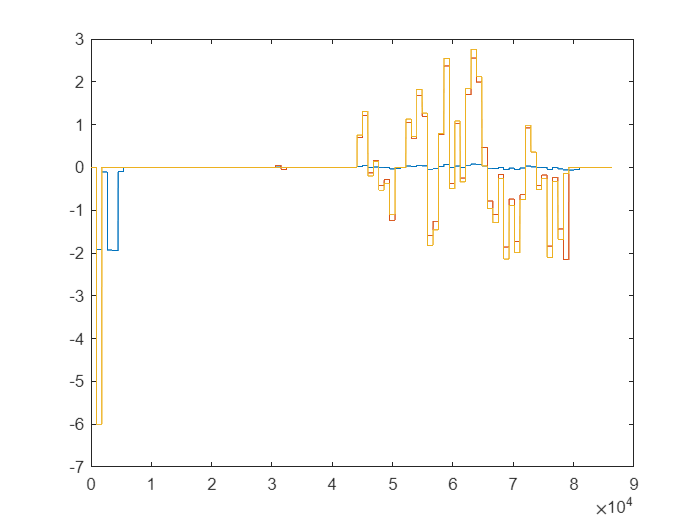

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
% saveas(gcf,'Figure/Hybrid','epsc')

figure()
plot(X(15:15+noPVInv-1,:)')